
d = load('glassMug_height.txt') % 컵 가장 윗부분에서 물까지의 높이

d =    10.4000
   10.0000
    9.6000
    9.4000
    9.2000
    9.0000
    8.8000
    8.6000
    8.4000
    8.2000


H = 10.4 % 컵 높이

H = 10.4000


fd = load("2cup_freq.txt")

fd =    601   600   600   600   600   599   598   598   597   596   595   594   591   590   588   584   580   575   573   569   562   553   547   542   536   526   517   509   499   489   480   467   457   449   438   427   416   405   396   384   372   363   352   342   331   326




rate = 48000;
intervalT = .5 * rate;

lfCut = 200;
nfft = 2^nextpow2(intervalT);

f = fd + lfCut;
f = f / nfft * rate;

Hd = (d ./ 10.4)

Hd =     1.0000
    0.9615
    0.9231
    0.9038
    0.8846
    0.8654
    0.8462
    0.8269
    0.8077
    0.7885


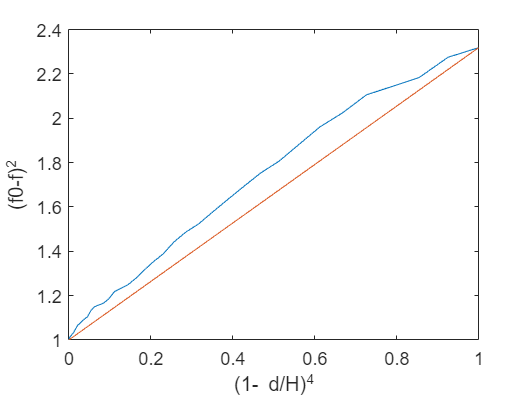


Y = (f(1) ./ f).^2; % (f0 - f)^2
X = (1 - Hd).^4;

clf
start = 1;
last = length(X) - 0;

figure
plot(X(start:last), Y(start:last))
hold on
plot(X([start, last]), Y([start, last]))
xlabel('(1- d/H)^4')
ylabel('(f0-f)^2')


% X = X.'
Y = Y.';
